Based on eqn. (45) and (24)-(27) in parametric amp below threshold notes


$$      G_{\mathrm{ext}}(\omega) = \frac{\frac{\kappa_{\mathrm{tot}}^2}{4} - \omega^2 + (\Delta + Ka^\dagger a)^2 - \vert \epsilon \vert^2 - \frac{\kappa_{\mathrm{ext}} \kappa_{\mathrm{tot}}}{2} - i\omega\kappa_{\mathrm{tot}} + i\kappa_{\mathrm{ext}}(\omega + \Delta + Ka^\dagger a)}{\left(\frac{\kappa_{\mathrm{tot}}}{2} - i\omega \right)^2 + (\Delta + K a^\dagger a)^2 - \vert \epsilon \vert ^2} \\
      M_{\mathrm{ext}}(\omega) = \frac{i \epsilon^* \kappa_{\mathrm{ext}}}{\left(\frac{\kappa_{\mathrm{tot}}}{2} - i\omega \right)^2 + (\Delta + K a^\dagger a)^2 - \vert \epsilon \vert ^2} \\
      M_{\mathrm{int}}(\omega) = \frac{i \epsilon^* \sqrt{\kappa_{\mathrm{ext}}\kappa_{\mathrm{int}}}}{\left(\frac{\kappa_{\mathrm{tot}}}{2} - i\omega \right)^2 + (\Delta + K a^\dagger a)^2 - \vert \epsilon \vert ^2} \\
      G_{\mathrm{int}}(\omega) = \frac{-\left(\frac{\kappa_{\mathrm{tot}}}{2}-i(\omega+\Delta + K a^\dagger a)\right)\sqrt{\kappa_{\mathrm{int}}\kappa_{\mathrm{ext}}}}{\left(\frac{\kappa_{\mathrm{tot}}}{2} - i\omega \right)^2 + (\Delta + K a^\dagger a)^2 - \vert \epsilon \vert ^2} 
$$



$$P_{\mathrm{SA}}(\omega, \Delta\omega) = \frac{4\hbar\omega_0}{\pi}\vert \alpha_{\mathrm{LO}}\vert^2\vert \alpha_{\mathrm{in}}\vert ^2 \big[\vert G_{\mathrm{ext}} (\omega)\vert ^2 +e^{-2i\Phi_{\mathrm{LO}}} G_{\mathrm{ext}}^*(\omega)M_{\mathrm{ext}}^*(-\omega) +\vert M_{\mathrm{ext}}(-\omega) \vert ^2  + e^{2i\Phi_{\mathrm{LO}}}G_{\mathrm{ext}}(\omega)M_{\mathrm{ext}}(-\omega) \big]$$



$$\Delta = \omega_0 - \frac{\omega_p}{2}$$


$\omega = \omega_s - \frac{\omega_p}{2} $ where $\omega_s
$ is the frequency of interest at which we record the output spectrum and $\omega \approx \kappa_{tot}$ in the rotating frame.

below, input_detunings = $\omega_s - \omega_0$

and pump_detunings = $\Delta
$

so correcting, by setting input_detunings_array = input_detunings_array + pump_detunings_array    

ng_value = 0;
flux_value = 0.125;
kerr = find_kerr_MHz_ng_flux(ng_value, flux_value)*1e6;
kappa_int = .3e6;
kappa_ext = 1.2e6;
kappa_tot = kappa_int + kappa_ext; 
pump_phase = 0;
cavity_classical_number = 1;

input_detunings_from_resonance = linspace(-3*kappa_tot, 3*kappa_tot, 201);
pump_detunings = linspace(-2e6, 2e6, 101);
pump_powers = linspace(0.1*kappa_tot/2, 5*kappa_tot/2, 50);
pump_powers = pump_powers *exp(1i*pump_phase);
input_phases = linspace(-pi, pi, 37);
[input_detunings_array, pump_detunings_array, pump_powers_array, input_phases_array] = ...
    ndgrid(input_detunings_from_resonance, pump_detunings, pump_powers, input_phases);
input_detunings_array = input_detunings_array + pump_detunings_array;   % this input_detunings_array is the detuning from half pump freq

%%% classical parametric oscillation oscillation amp %%%
cavity_classical_number = zeros(size(pump_detunings_array)); % units of photon number
if kerr > 0
    non_zero_classical_indices = and(sqrt(abs(pump_powers_array).^2 - kappa_tot^2/4) - pump_detunings_array > 0, ...
        abs(pump_powers_array).^2 - kappa_tot^2/4 > 0);
    cavity_classical_number (non_zero_classical_indices) = 1/kerr *(-pump_detunings_array(non_zero_classical_indices) + ...
            sqrt(abs(pump_powers_array(non_zero_classical_indices)).^2 - kappa_tot^2/4)) %units of photon number
elseif kerr < 0 
    non_zero_classical_indices = and(-sqrt(abs(pump_powers_array).^2 - kappa_tot^2/4) - pump_detunings_array < 0, ...
        abs(pump_powers_array).^2 - kappa_tot^2/4 > 0);
    cavity_classical_number (non_zero_classical_indices)= 1/kerr *(-pump_detunings_array(non_zero_classical_indices)- ...
            sqrt(abs(pump_powers_array(non_zero_classical_indices)).^2 - kappa_tot^2/4)); %units of photon number
end
cavity_classical_number(cavity_classical_number < 1) = 1;  % we put in an input tone of 1 photon at the least, even if below threshold

g_ext = (kappa_tot^2/4 - input_detunings_array.^2 + (pump_detunings_array + kerr*cavity_classical_number).^2 - abs(pump_powers_array).^2 - kappa_ext*kappa_tot/2 ...
    -1i*input_detunings_array*kappa_tot + 1i*kappa_ext.*(input_detunings_array + pump_detunings_array + kerr*cavity_classical_number))./ ...
    ((kappa_tot/2 - 1i*input_detunings_array).^2 + (pump_detunings_array + kerr*cavity_classical_number).^2 - abs(pump_powers_array).^2);

g_ext_epsilon_0 = (kappa_tot^2/4 - input_detunings_array.^2 + (pump_detunings_array + kerr*cavity_classical_number).^2 - kappa_ext*kappa_tot/2 ...
    -1i*input_detunings_array*kappa_tot + 1i*kappa_ext.*(input_detunings_array + pump_detunings_array + kerr*cavity_classical_number))./ ...
    ((kappa_tot/2 - 1i*input_detunings_array).^2 + (pump_detunings_array + kerr*cavity_classical_number).^2);

m_ext = 1i*conj(pump_powers_array)*kappa_ext./((kappa_tot/2 - 1i*input_detunings_array).^2 + (pump_detunings_array + kerr*cavity_classical_number).^2 - abs(pump_powers_array).^2);

output_power = 4/pi*(abs(g_ext).^2 + abs(flip(m_ext, 1)).^2 + exp(-2*1i*input_phases_array).*conj(g_ext).*conj(flip(m_ext, 1)) + exp(2*1i*input_phases_array).* ...
    g_ext.*flip(m_ext,1));

output_power_pump_off = 4/pi*(abs(g_ext_epsilon_0)).^2;

power_gain = output_power./output_power_pump_off;
power_gain_dB = 10*log10(power_gain);

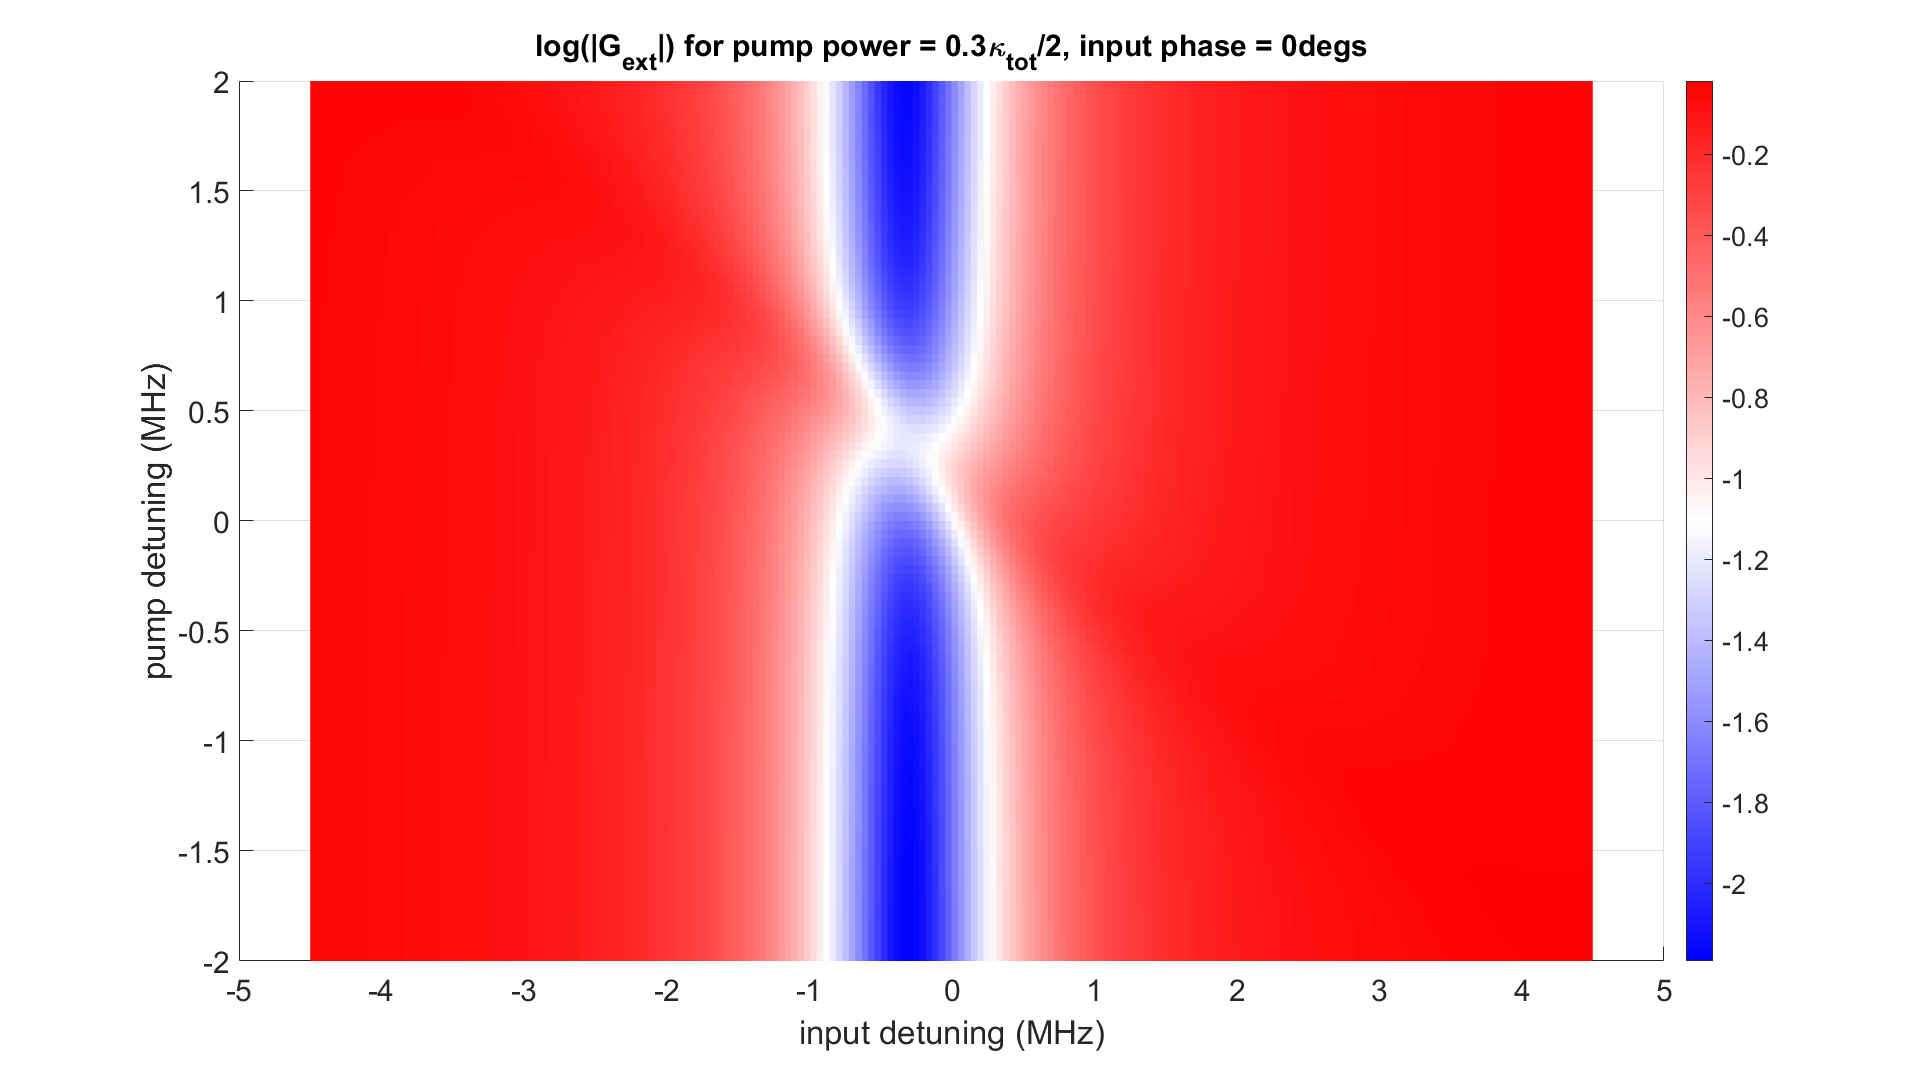

pump_power_number = 3;
input_phase_number = 19;
pump_detuning_number = 51;
% input_detuning_number = find(abs(input_detunings_from_resonance + .36e6 )< mean(diff(input_detunings_from_resonance)));
input_detuning_number = 101;
% input_detuning_number = find(abs(squeeze(input_detunings_array(:, pump_detuning_number, pump_power_number, input_phase_number)) + .36e6 < mean(diff(input_detunings_from_resonance))),1);
mod_g_ext = abs(g_ext);
mod_g_ext(mod_g_ext> 100) = 100;
mod_g_ext_pump_off = abs(g_ext_epsilon_0);
mod_g_ext_pump_off(g_ext_epsilon_0> 100) = 100;

figure
surf(input_detunings_from_resonance/1e6, pump_detunings/1e6, 10*log10(squeeze(mod_g_ext(:,:, pump_power_number, input_phase_number)))', 'LineStyle','none')
view(0,90)
title(['log(|G_{ext}|) for pump power = ' num2str(pump_powers(pump_power_number)/kappa_tot*2) '\kappa_{tot}/2, ' ...
    'input phase = ' num2str(input_phases(input_phase_number)*180/pi) 'degs'])
a=colorbar;
ylabel(a,'Output spectrum (arb. units)','FontSize',18,'Rotation',270)%,'Interpreter','latex');
a.Label.Position = [5, 0];
xlabel('input detuning (MHz)')
ylabel('pump detuning (MHz)')
colormap('redblue')
colorbar

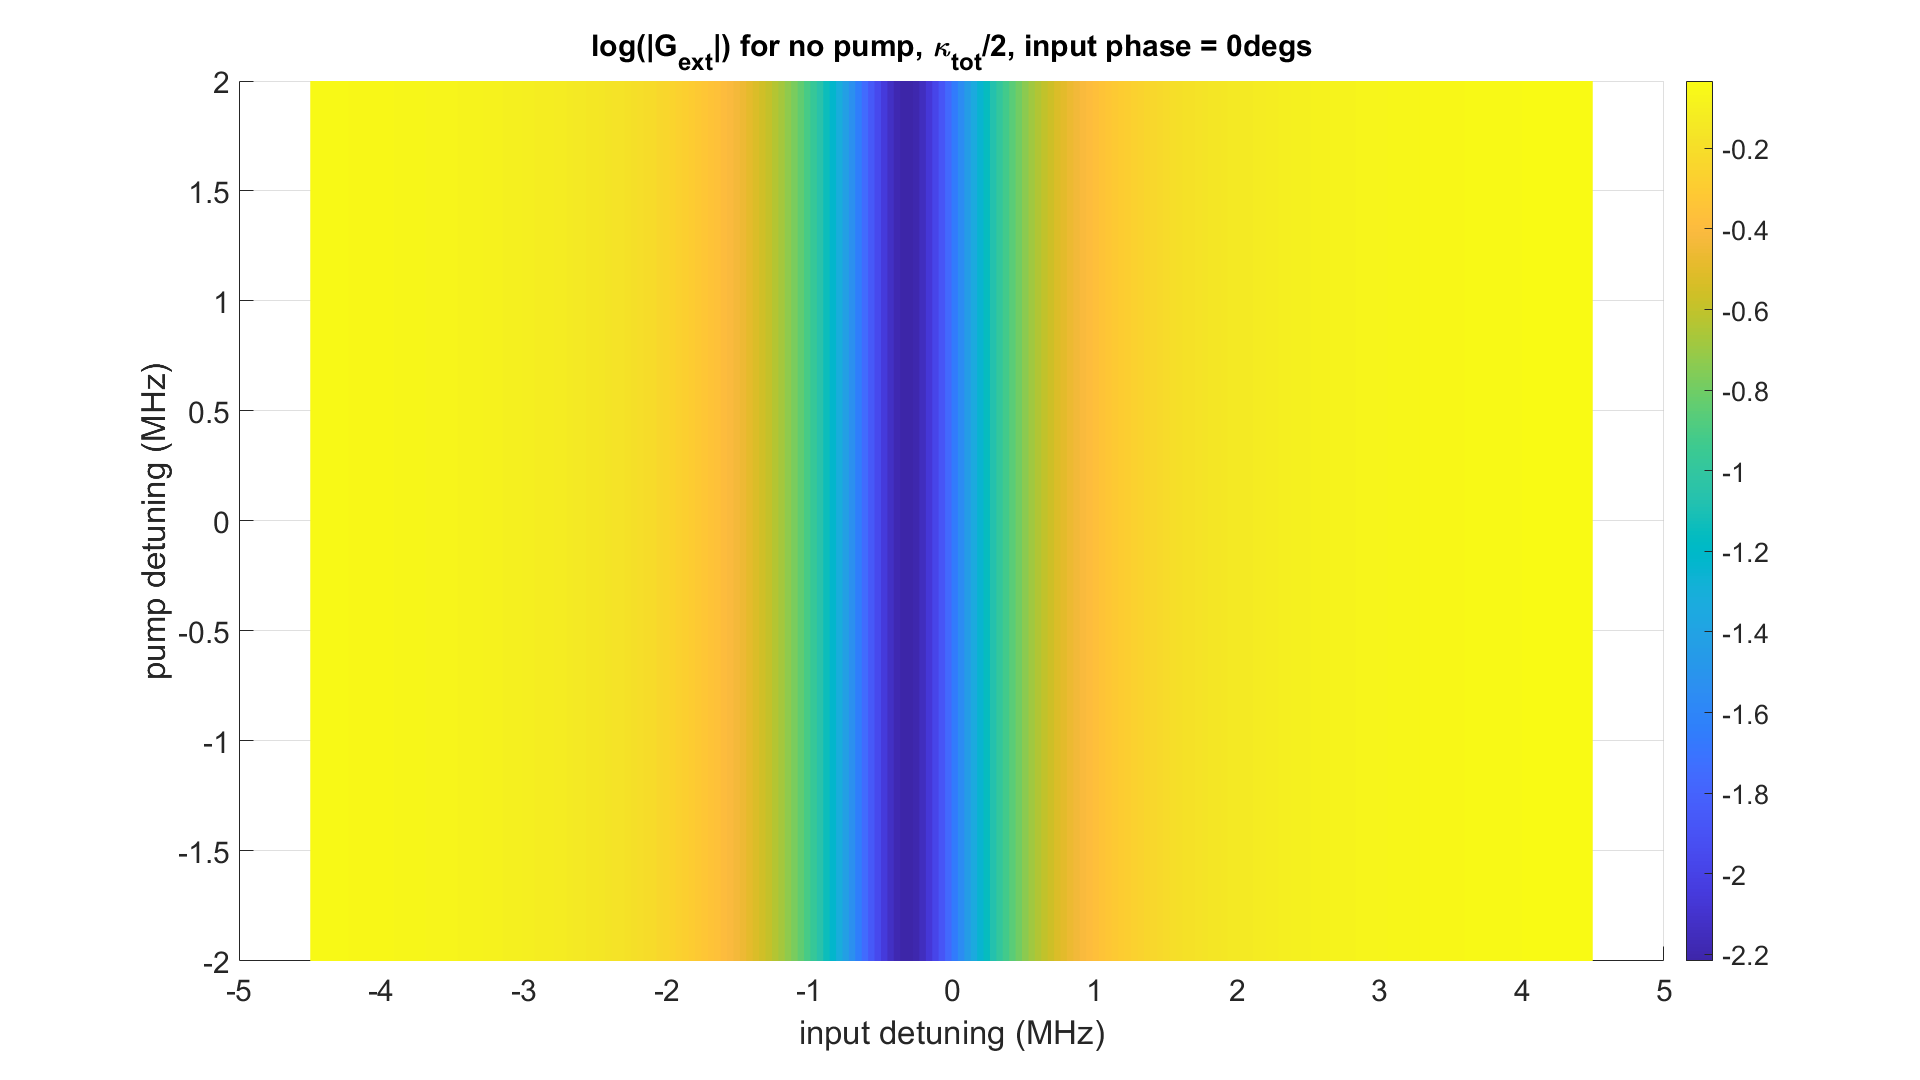

% caxis([0 10])

figure
surf(input_detunings_from_resonance/1e6, pump_detunings/1e6, 10*log10(squeeze(mod_g_ext_pump_off(:,:, pump_power_number, input_phase_number)))', 'LineStyle','none')
view(0,90)
title(['log(|G_{ext}|) for no pump, \kappa_{tot}/2, ' ...
    'input phase = ' num2str(input_phases(input_phase_number)*180/pi) 'degs'])
a=colorbar;
ylabel(a,'Output spectrum (arb. units)','FontSize',18,'Rotation',270)%,'Interpreter','latex');
a.Label.Position = [5, 0];
xlabel('input detuning (MHz)')
ylabel('pump detuning (MHz)')
colorbar

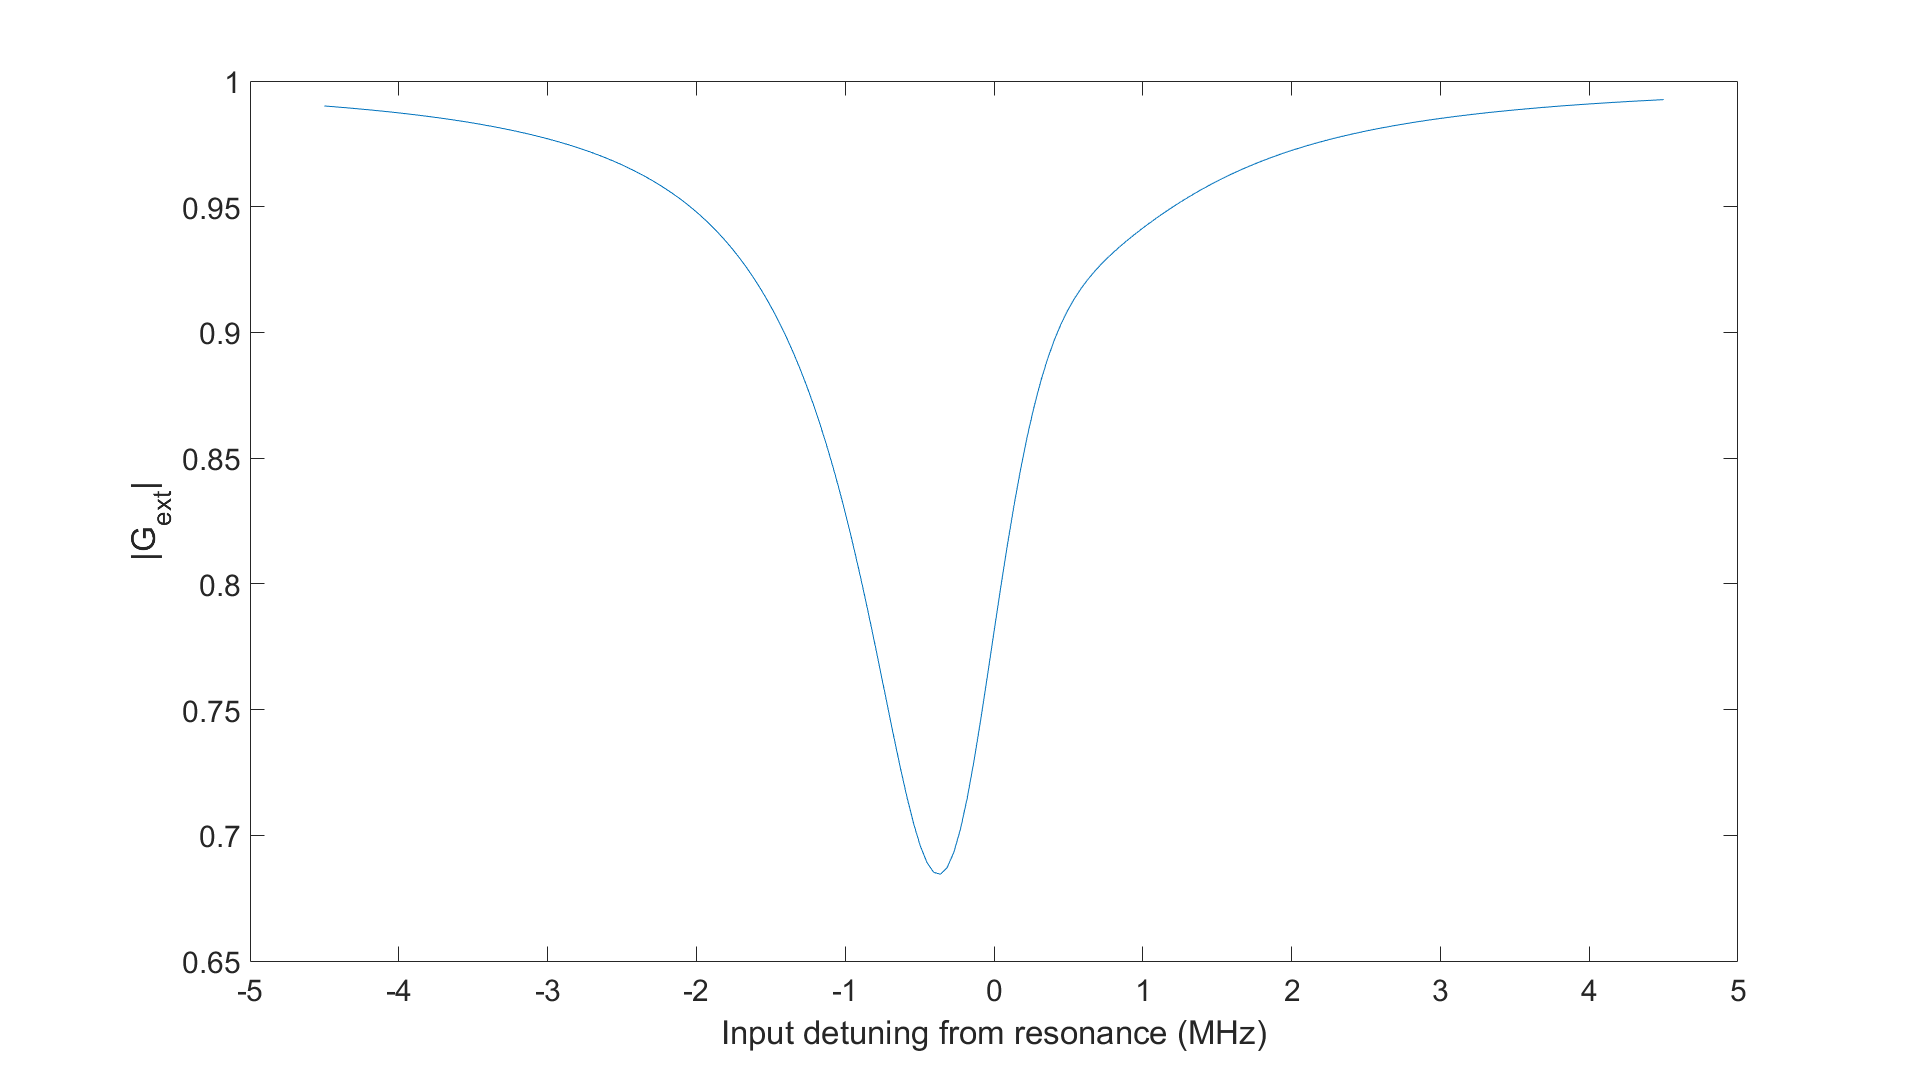


figure
plot(input_detunings_from_resonance/1e6, squeeze(mod_g_ext(:,pump_detuning_number, pump_power_number, input_phase_number)))
xlabel('Input detuning from resonance (MHz)')
ylabel('|G_{ext}|')

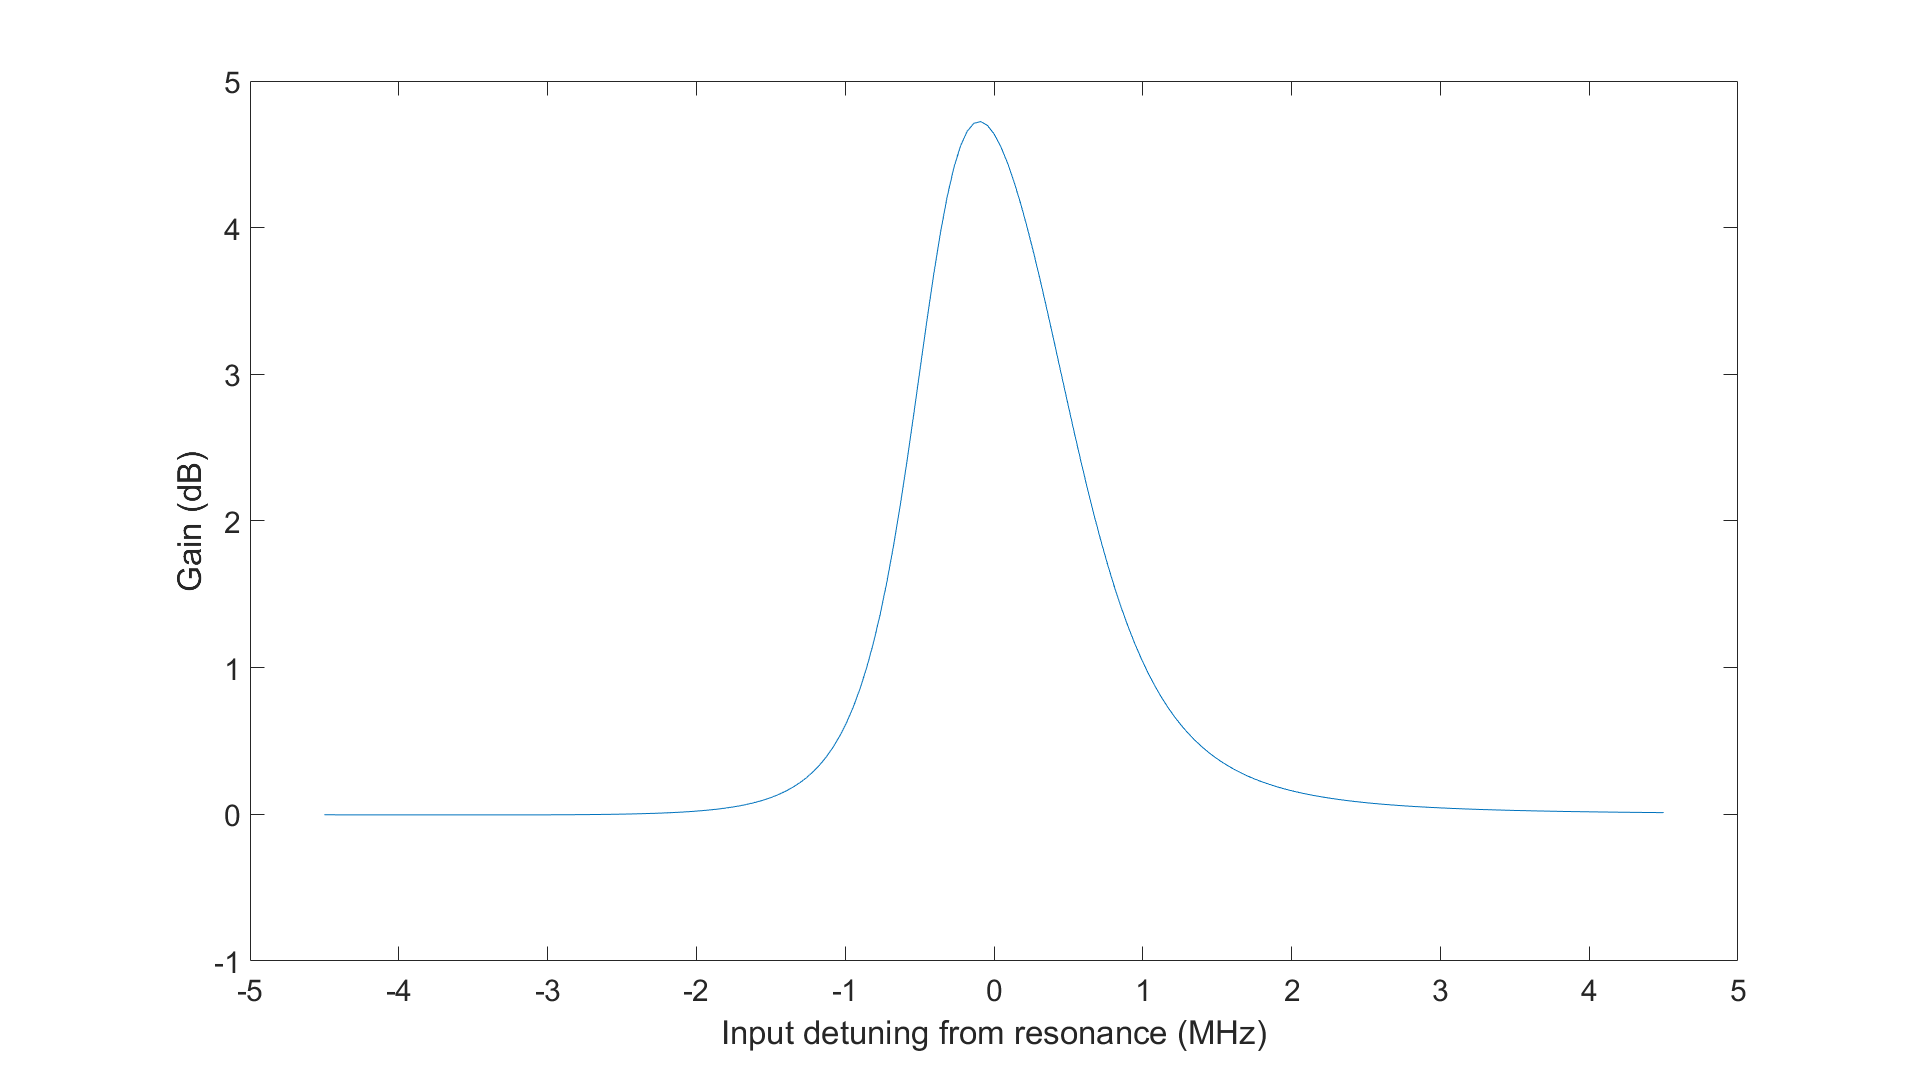


figure
plot(input_detunings_from_resonance/1e6, squeeze(power_gain_dB(:,pump_detuning_number, pump_power_number, input_phase_number)))
xlabel('Input detuning from resonance (MHz)')
ylabel('Gain (dB)')

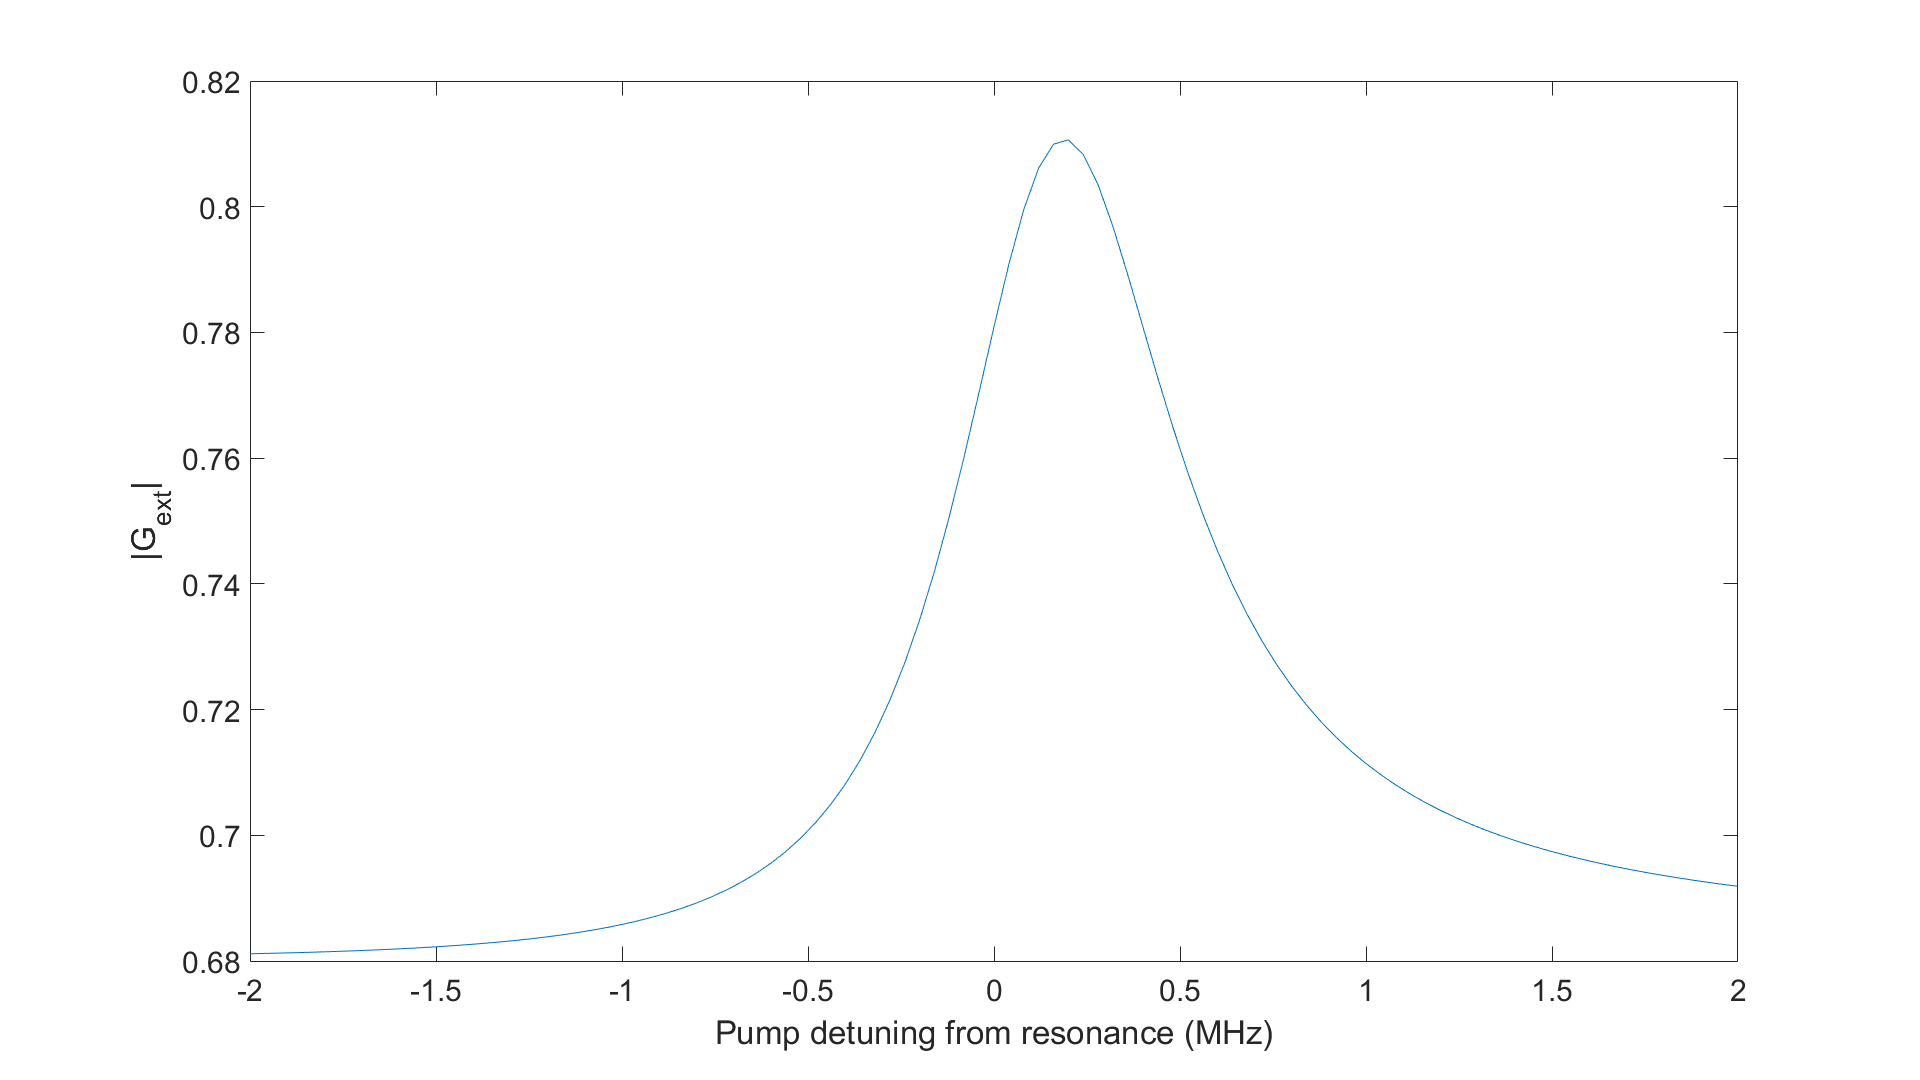


figure
plot(pump_detunings/1e6, squeeze(mod_g_ext(input_detuning_number,:, pump_power_number, input_phase_number)))
xlabel('Pump detuning from resonance (MHz)')
ylabel('|G_{ext}|')

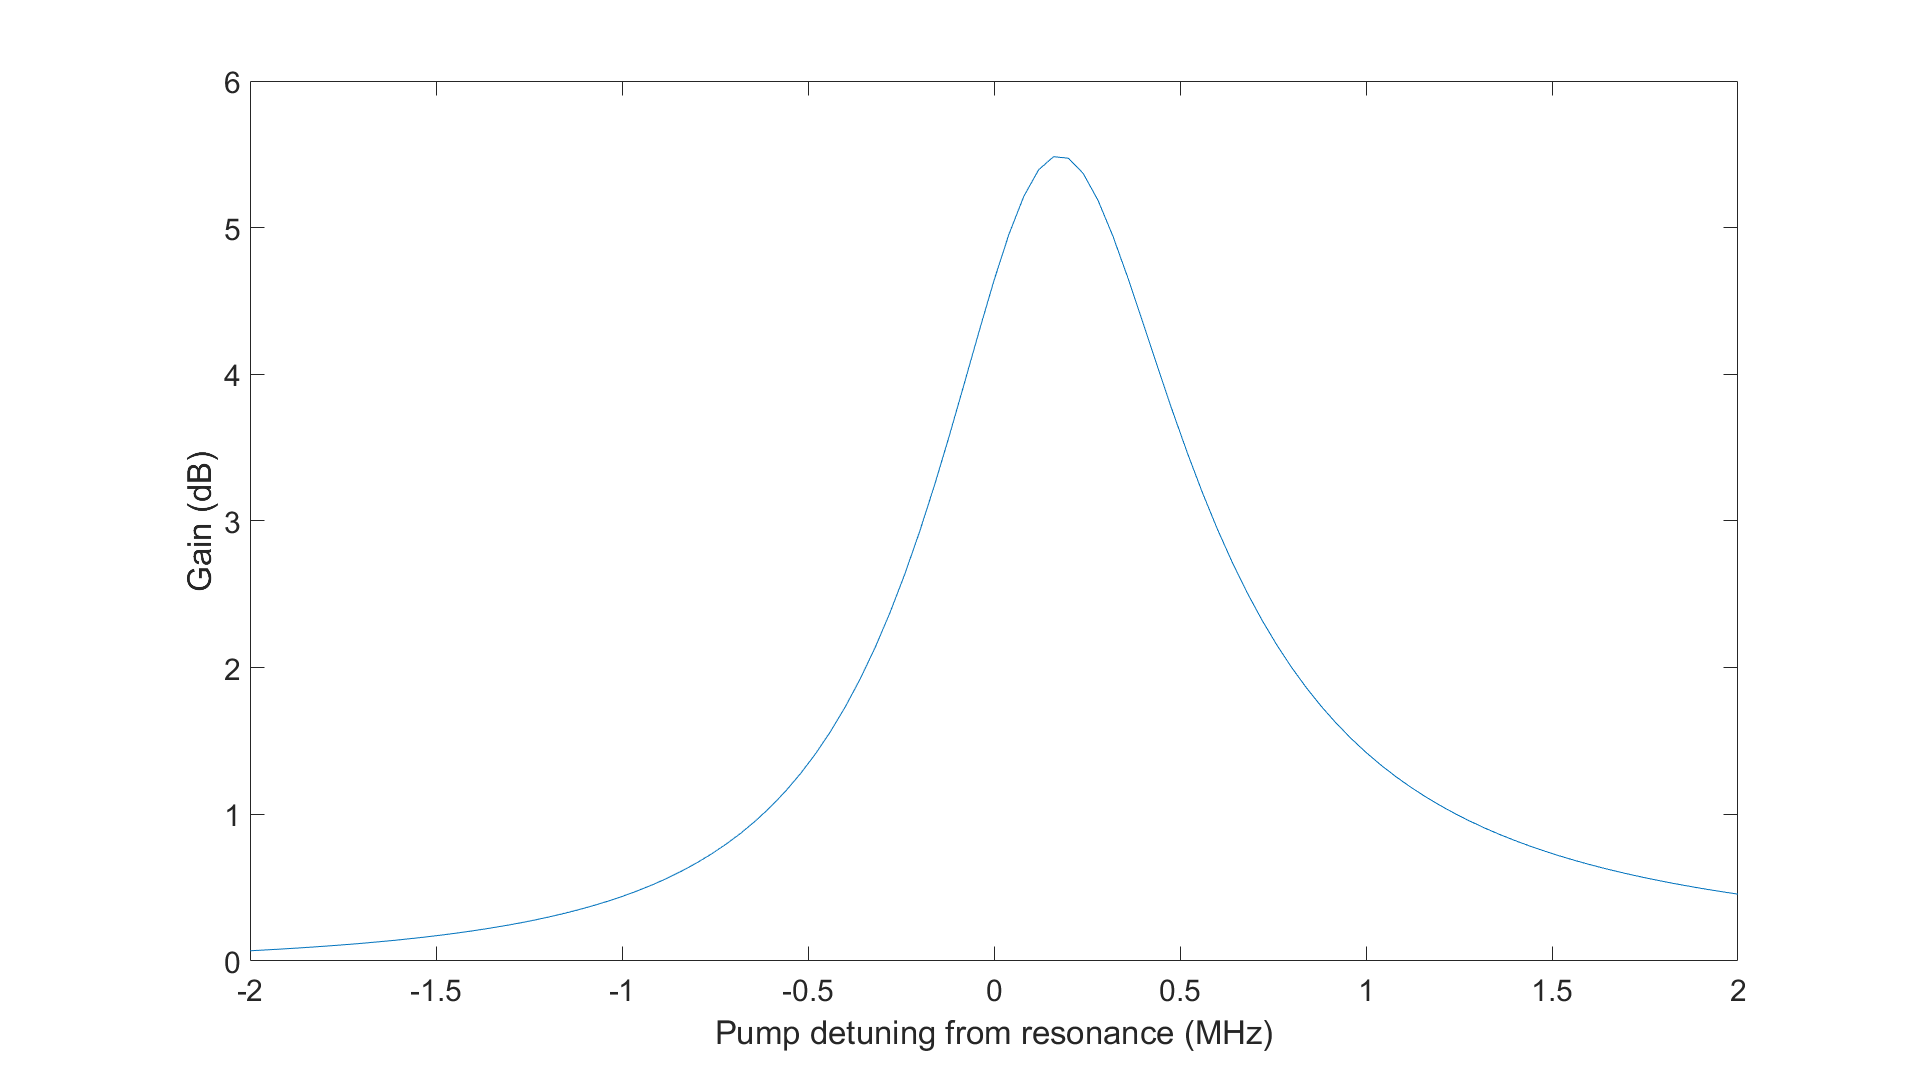


figure
plot(pump_detunings/1e6, squeeze(power_gain_dB(input_detuning_number,:, pump_power_number, input_phase_number)))
xlabel('Pump detuning from resonance (MHz)')
ylabel('Gain (dB)')

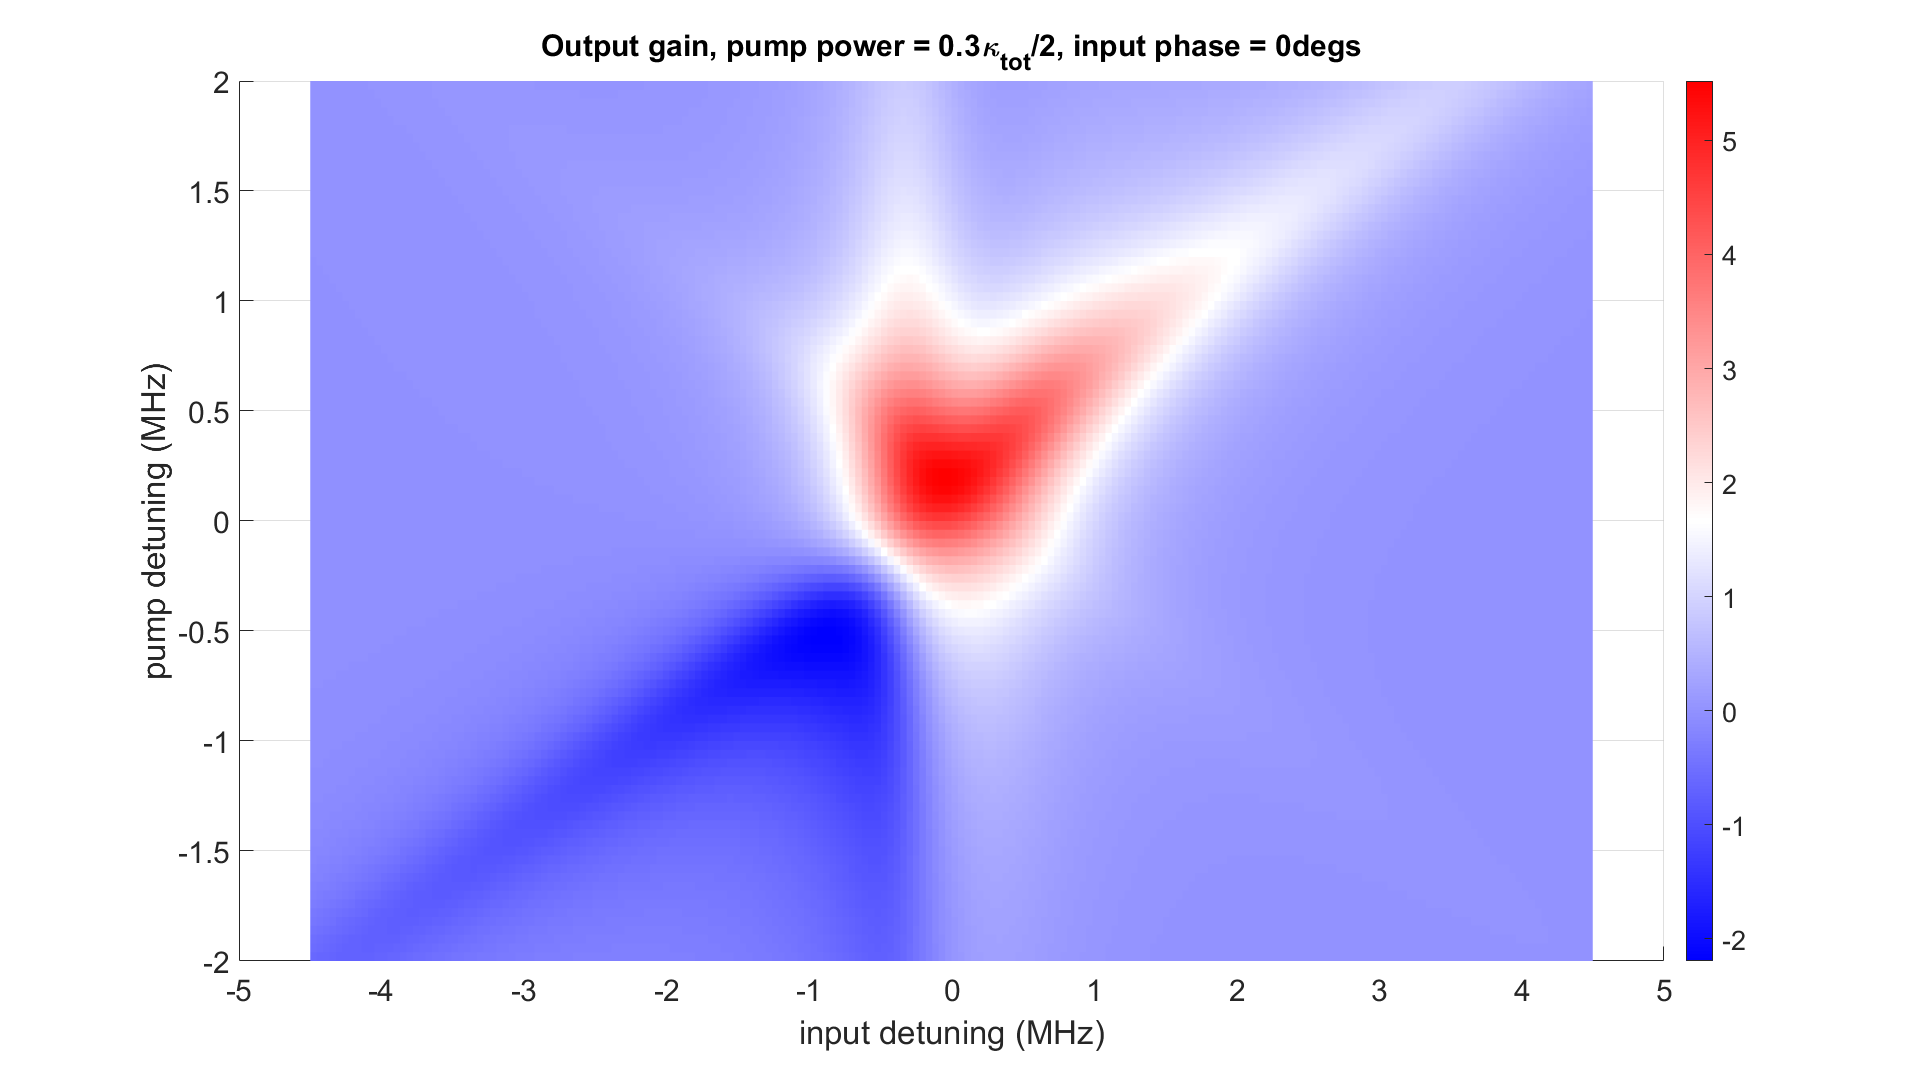




% figure
% surf(input_detunings_from_resonance/1e6, pump_detunings/1e6, cavity_classical_number(:,:, pump_power_number, input_phase_number)')
% view(0,90)
% colorbar

figure
surf(input_detunings_from_resonance/1e6, pump_detunings/1e6, squeeze(power_gain_dB(:,:, pump_power_number, input_phase_number))', 'LineStyle','none')
view(0,90)
title(['Output gain, pump power = ' num2str(pump_powers(pump_power_number)/kappa_tot*2) '\kappa_{tot}/2, ' ...
    'input phase = ' num2str(input_phases(input_phase_number)*180/pi) 'degs'])
a=colorbar;
a.Label.String = 'Gain(dB)';
a.Label.FontSize = 18;
a.Label.Visible = 'on';
a.Label.Rotation = 90;
% ylabel(a,'Gain (dB)','FontSize',18,'Rotation',270)%,'Interpreter','latex');
a.Label.Position = [2.990123492111408,7.20495790057408,0];
xlabel('input detuning (MHz)')
ylabel('pump detuning (MHz)')
colorbar
colormap(redblue)

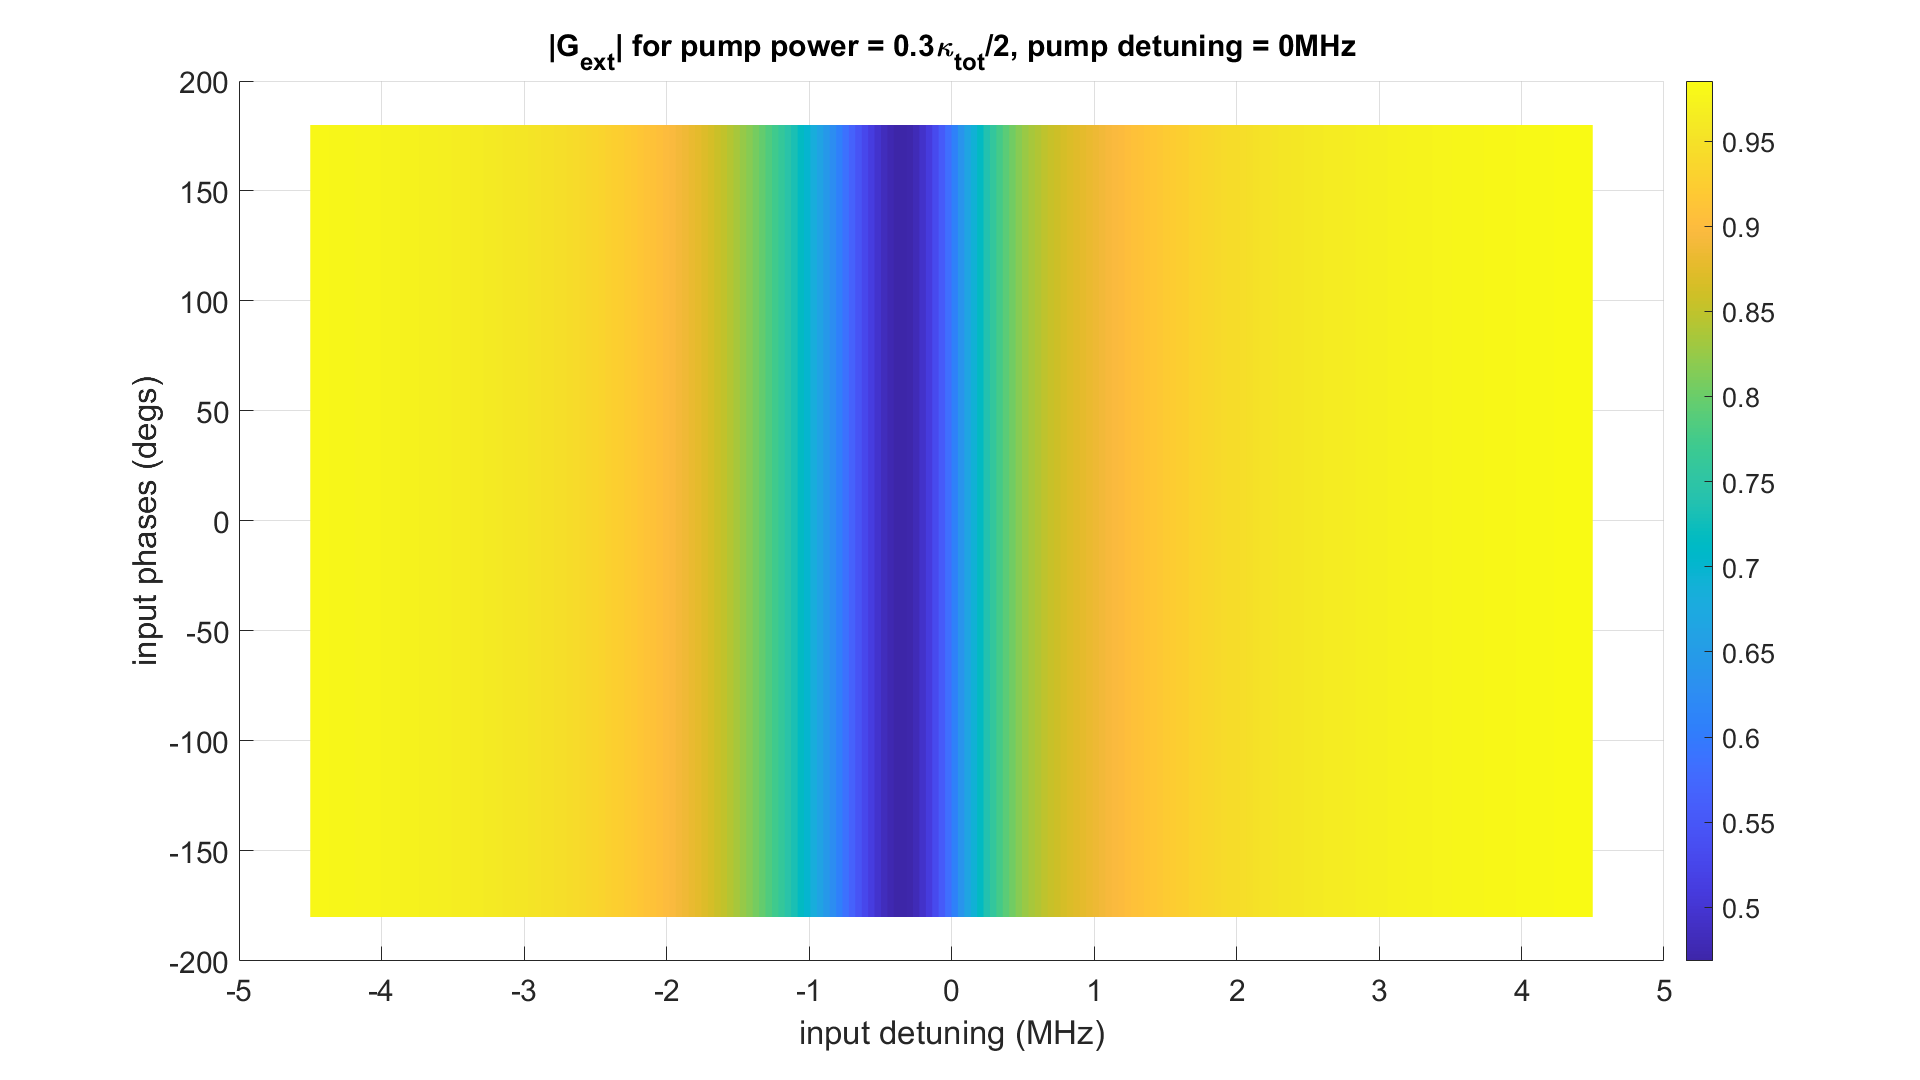

% caxis([0 30])

figure
surf(input_detunings_from_resonance/1e6, 180/pi*input_phases, abs(squeeze(g_ext(:,pump_detuning_number, pump_power_number, :))).^2', 'LineStyle','none')
view(0,90)
title(['|G_{ext}| for pump power = ' num2str(pump_powers(pump_power_number)/kappa_tot*2) '\kappa_{tot}/2, ' ...
    'pump detuning = ' num2str(pump_detunings(pump_detuning_number)/1e6) 'MHz'])
a=colorbar;
ylabel(a,'Output spectrum (arb. units)','FontSize',18,'Rotation',270)%,'Interpreter','latex');
a.Label.Position = [5, 0];
xlabel('input detuning (MHz)')
ylabel('input phases (degs)')
colorbar

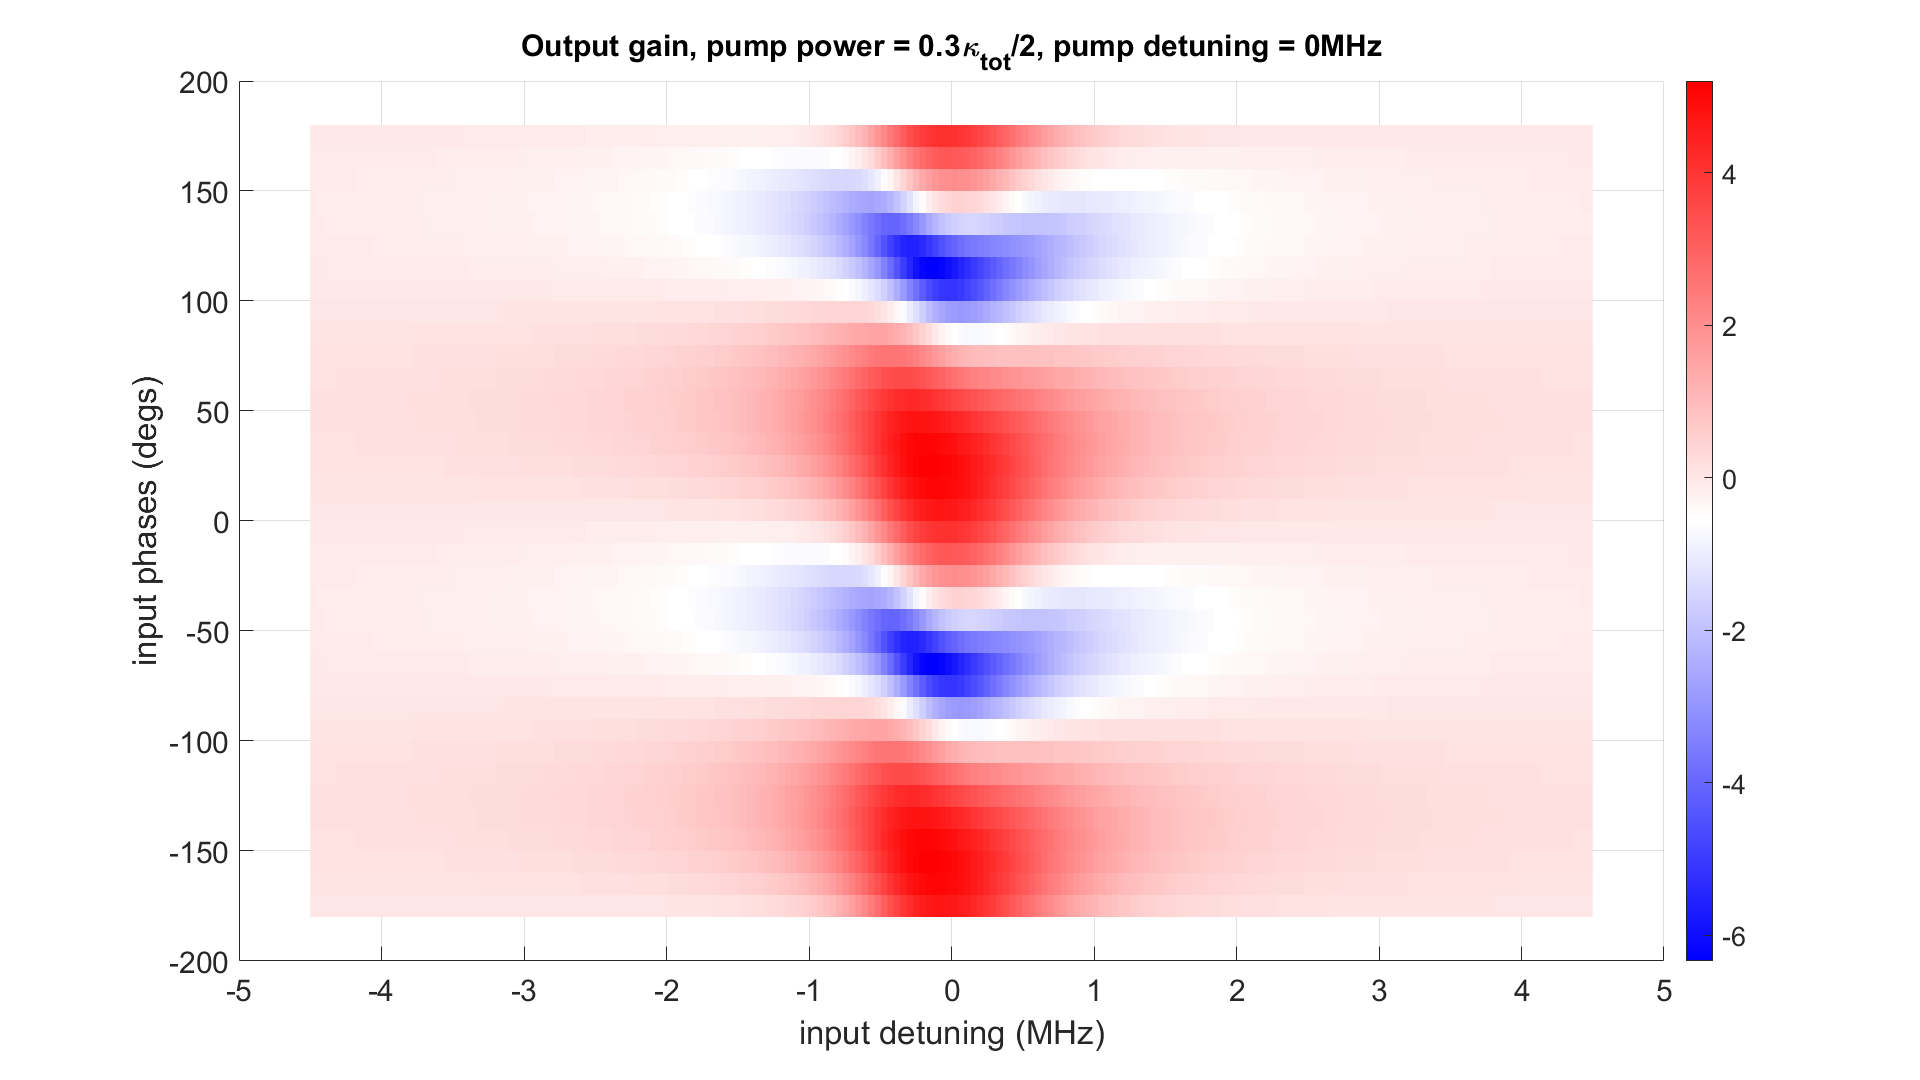

% caxis([0 10])

figure
surf(input_detunings_from_resonance/1e6, 180/pi*input_phases, squeeze(power_gain_dB(:,pump_detuning_number, pump_power_number, :))', 'LineStyle','none')
view(0,90)
title(['Output gain, pump power = ' num2str(pump_powers(pump_power_number)/kappa_tot*2) '\kappa_{tot}/2, ' ...
    'pump detuning = ' num2str(pump_detunings(pump_detuning_number)/1e6) 'MHz'])
a=colorbar;
ylabel(a,'Gain (dB)','FontSize',18,'Rotation',270)%,'Interpreter','latex');
a.Label.Position = [0, 0];
xlabel('input detuning (MHz)')
ylabel('input phases (degs)')
colorbar
colormap(redblue)

% caxis([0 30])

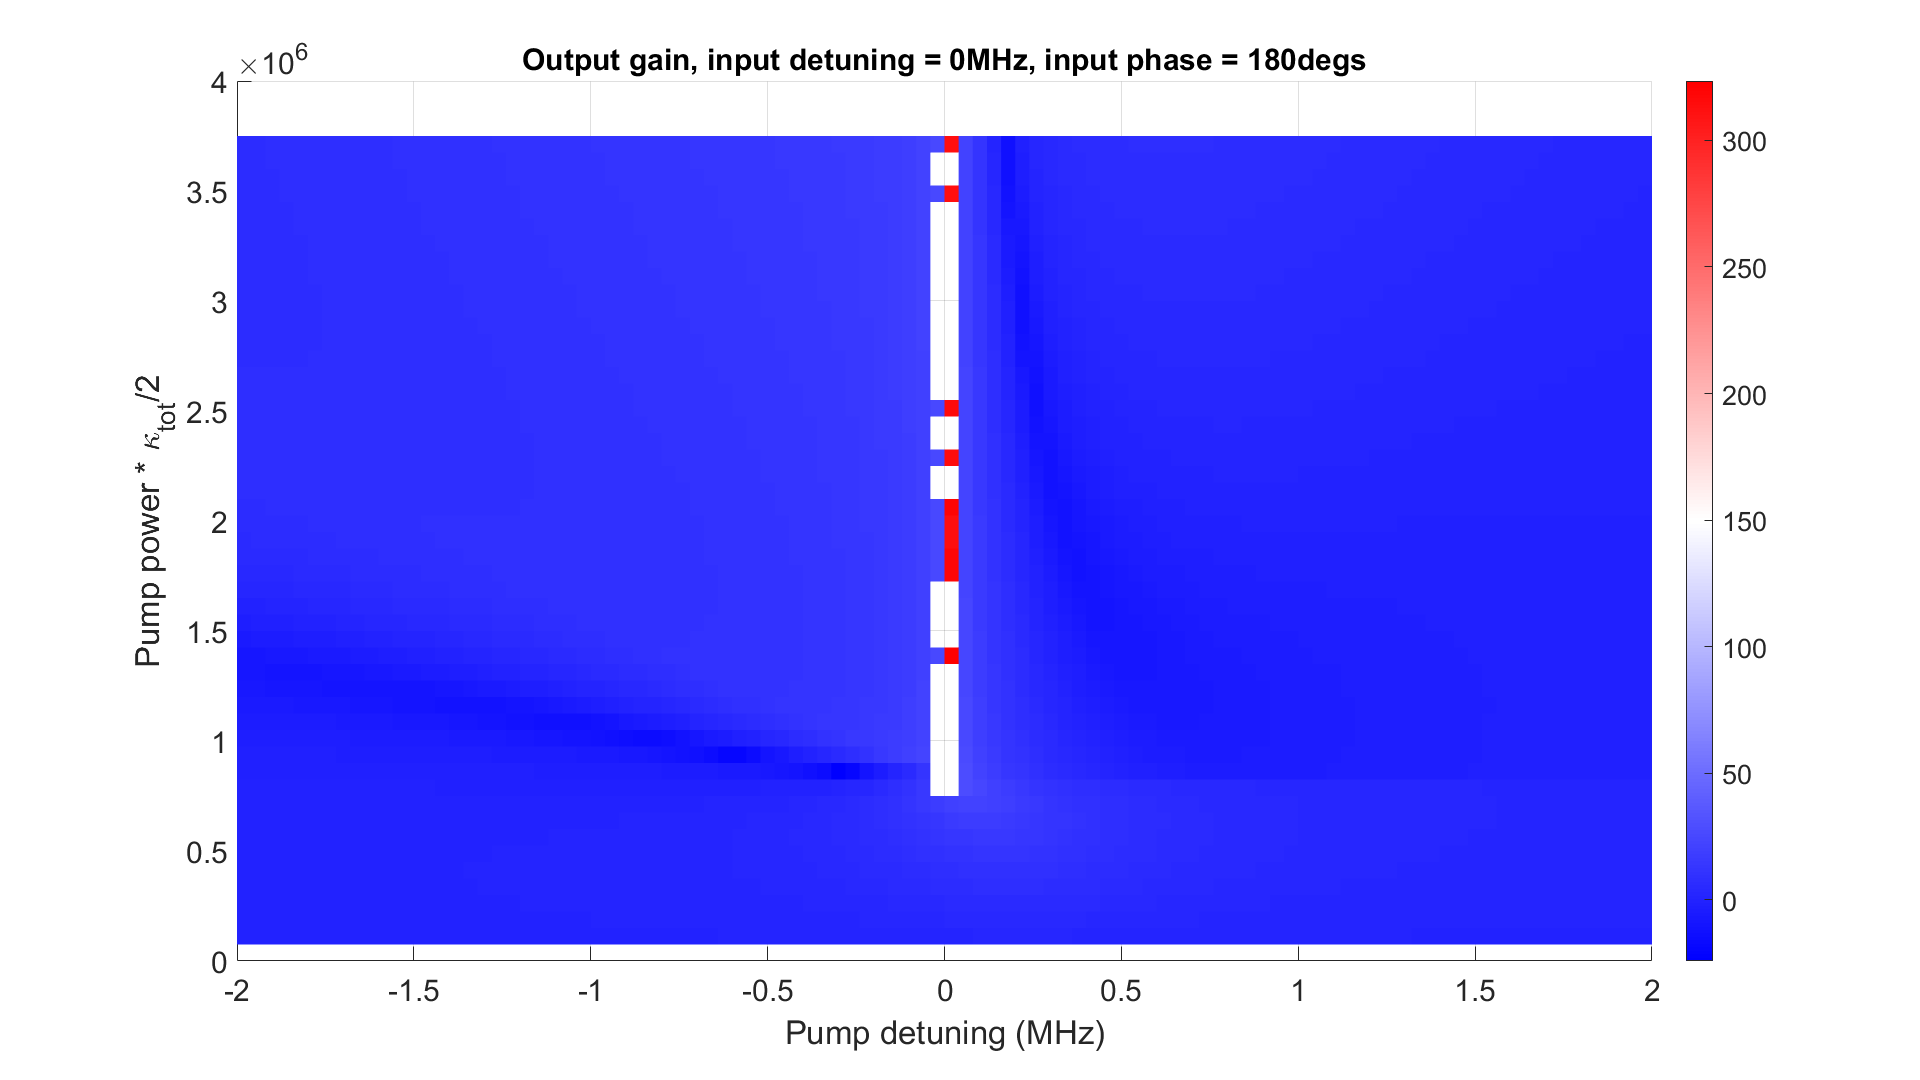

input_phase_number = 37;
figure
surf(pump_detunings/1e6, pump_powers, squeeze(real(power_gain_dB(input_detuning_number,:, :, input_phase_number)))', 'LineStyle','none')
view(0,90)
title(['Output gain, input detuning = ' num2str(input_detunings_from_resonance(input_detuning_number)/1e6) 'MHz, ' ...
    'input phase = ' num2str(180/pi*input_phases(input_phase_number)) 'degs'])
a=colorbar;
ylabel(a,'Gain (dB)','FontSize',18,'Rotation',270)%,'Interpreter','latex');
a.Label.Position = [0, 0];
xlabel('Pump detuning (MHz)')
ylabel('Pump power * \kappa_{tot}/2')
colorbar
colormap(redblue)

% caxis([0 30])

g_ext(101, 51, 9, 19)

ans = -3.1371 - 1.8350i